# Specify Delimiter and Empty Value Conversion

Load the file `data.csv` and preview its contents in a text editor. A screen shot is shown below. Notice the file contains data separated by commas and also contains empty values.

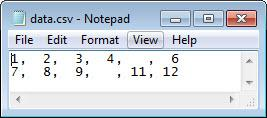

Read the file, converting empty cells to `-Inf`.

filename = 'data.csv';
fileID = fopen(filename);
C = textscan(fileID,'%f %f %f %f %u8 %f',...
'Delimiter',',','EmptyValue',-Inf);
fclose(fileID);
column4 = C{4}, column5 = C{5}

`textscan` returns a `1-by-6` cell array, `C`. The `textscan` function converts the empty value in `C{4}` to `-Inf`, where `C{4}` is associated with a floating-point format. Because MATLAB® represents unsigned integer `-Inf` as `0`, `textscan` converts the empty value in `C{5}` to `0`, and not  `-Inf`.

*Copyright 2012 The MathWorks, Inc.*